# Chapter 6, Section 3 (Part 3)

The goal in this activity is to introduce the Gram-Schmidt Process, a method for finding an orthogonal basis for a finite dimensional inner product space. Our author proves a theorem that states that any finite dimensional inner product space has an orthogonal basis, but what we will start with are some examples with images to help understand the process.

# Example #1

Find an orthogonal basis for the vector space spanned by the two vectors


$$\textbf v_1=\pmatrix{1\cr -3\cr 0}\qquad\text{and}\qquad \textbf v_2=\pmatrix{2\cr 2\cr 0}$$


**Solution:** Let's begin with an image. The vector space spanned by these two vectors is all linear combinations of these two vectors, so we can write


$$\begin{array}{rcl}
\pmatrix{x\cr y\cr z}&=&s\pmatrix{1\cr -3\cr 0}+t\pmatrix{2\cr 2\cr 0}\\
\pmatrix{x\cr y\cr z}&=&\pmatrix{s+2t\cr -3s+2t\cr 0}
\end{array}$$


Now, we know this will be a plane, so let's sketch this plane and add our vectors $\textbf v_1$ and $\textbf v_2$ to our image.

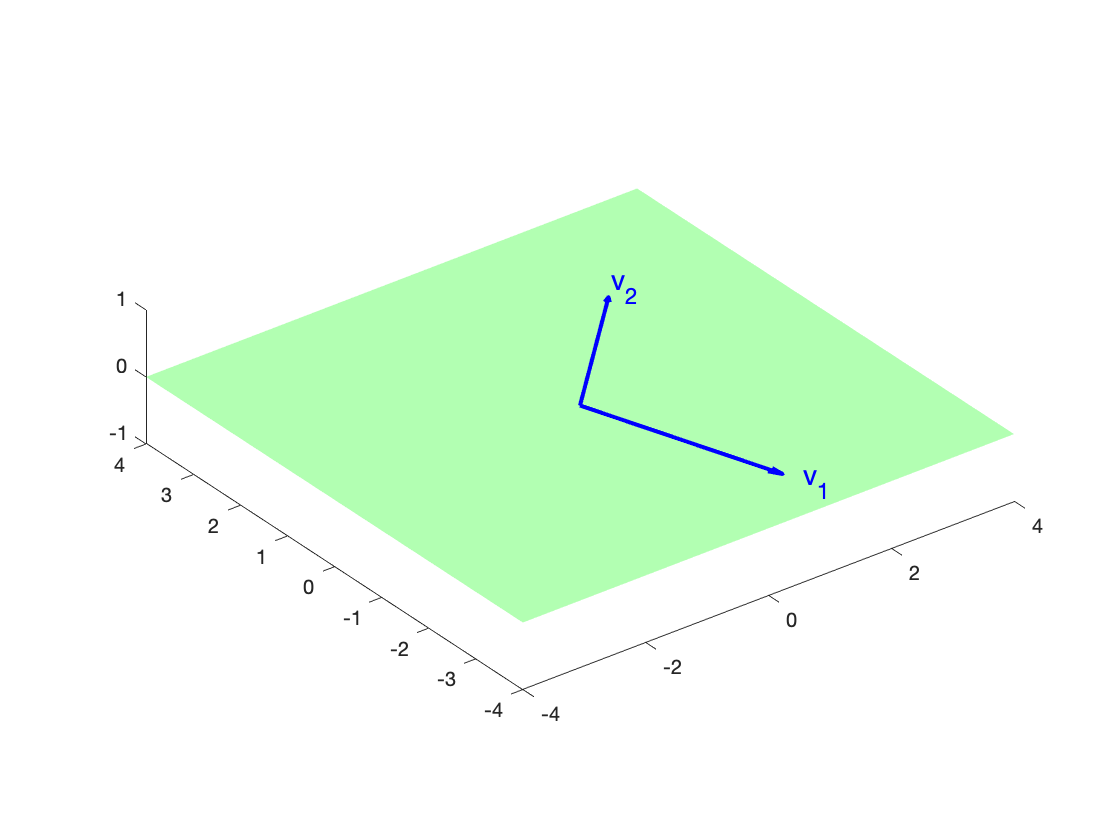

figure
hold on
v1=[1;-3;0]; v2=[2;2;0];
s=linspace(-4,4,20);
t=linspace(-4,4,20);
[S,T]=meshgrid(s,t);
X=S+2*T;
Y=-3*S+2*T;
Z=zeros(size(T));
surf(X,Y,Z,'EdgeColor','none','FaceColor','g','FaceAlpha',0.3)
quiver3(0,0,0,v1(1),v1(2),v1(3),0,'LineWidth',2,'Color','b')
quiver3(0,0,0,v2(1),v2(2),v2(3),0,'LineWidth',2,'Color','b')
axis equal
axis([-4,4,-4,4,-1,1])
text(1.1,-3.3,0,'v_1','Color','b','FontSize',14)
text(2.2,2.2,0,'v_2','Color','b','FontSize',14)
view(3)
hold off

Pretty clear evidence that they are not orthogonal, but let's check this with Matlab.

v1=[1;-3;0]; v2=[2;2;0]; dot(v1,v2)

ans = -4

The dot product is not zero, so they are not orthogonal. Now, we want to create an orthogonal basis $\{\textbf w_1,\ \textbf w_2\}$.

**Step 1:** Let $\textbf w_1=\textbf v_1=(1,-3,0)^T$.

**Step 2:** Let $\textbf w_2=\textbf v_2-\text{proj}_{\textbf w_1}\textbf v_2$. Let's calculate this result.


$$\begin{array}{rcl}
\textbf w_1&=&\text{proj}_{\textbf w_1}\textbf v_2\\
&=&\textbf v_2-\frac{\textbf v_2\cdot\textbf w_1}{\textbf w_1\cdot\textbf w_1}\,\textbf w_1\\
&=&\pmatrix{2\cr2\cr0}-\frac{(2,2,0)\cdot(1,-3,0)}{(1,-3,0)\cdot(1,-3,0)}\,\pmatrix{1\cr -3\cr 0}\\
&=&\pmatrix{2\cr2\cr0}-\frac{-4}{10}\,\pmatrix{1\cr -3\cr 0}\\
&=&\pmatrix{2\cr2\cr0}+\pmatrix{2/5\cr -6/5\cr 0}\\
&=&\pmatrix{12/5\cr 4/5\cr 0}
\end{array}$$


Let's check this with Matlab. 

v1=[1;-3;0]; v2=[2;2;0];
w1=v1

w1 =      1
    -3
     0


w2=sym(v2)-dot(v2,w1)/dot(w1,w1)*w1

$$w2 = \left(\begin{array}{c} \frac{12}{5}\\ \frac{4}{5}\\ 0 \end{array}\right)$$

Same as our hand-calculations. We will also want to add $\text{proj}_{\textbf w_1}\textbf v_2$ to our image, so we will calculate $\text{proj}_{\textbf w_1}\textbf v_2$ and store it in the variables p. 

p=dot(v2,w1)/dot(w1,w1)*w1

p =    -0.4000
    1.2000
         0


Now, let's add $\textbf w_1$, $\textbf w_2$, and $\text{proj}_{\textbf w_1}\textbf v_2$ to our image and show that this is successful.

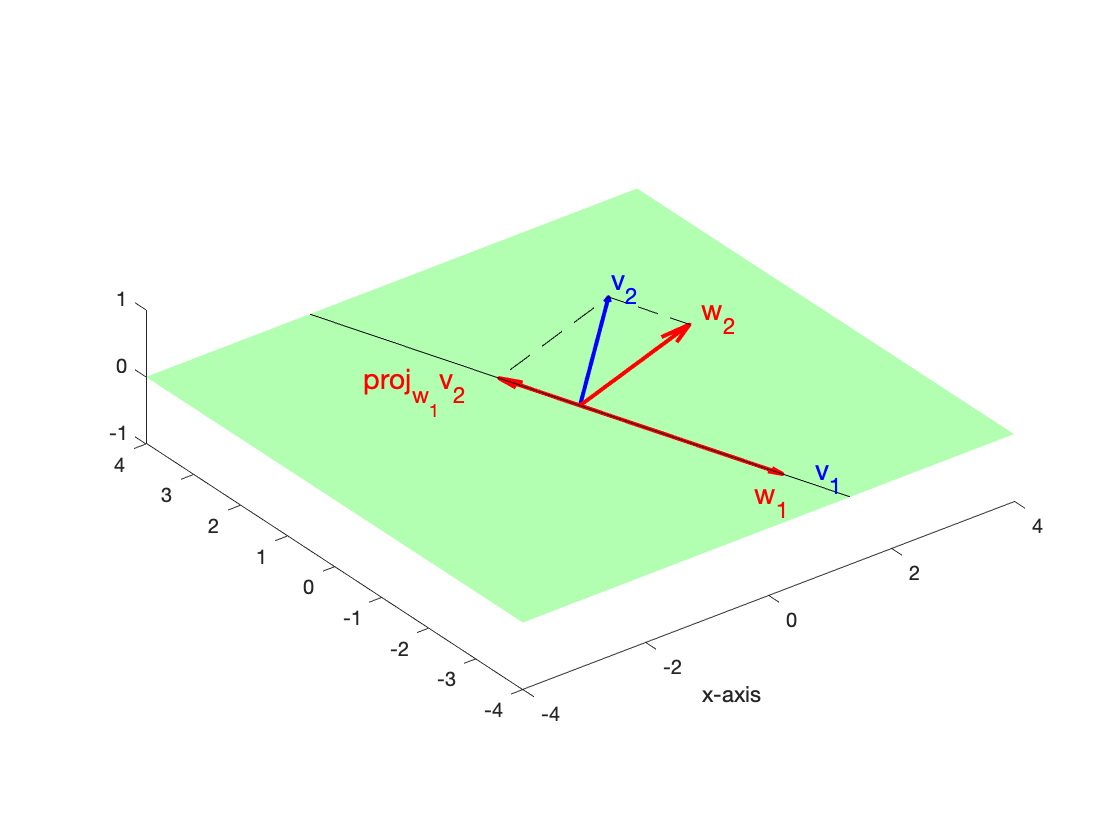

figure
hold on
v1=[1;-3;0];v2=[2;2;0];
w1=v1; proj=dot(v2,w1)/dot(w1,w1)*w1;w2=v2-proj;
s=linspace(-4,4,20);
t=linspace(-4,4,20);
[S,T]=meshgrid(s,t);
X=S+2*T;
Y=-3*S+2*T;
Z=zeros(size(T));
surf(X,Y,Z,'EdgeColor','none','FaceColor','g','FaceAlpha',0.3)
quiver3(0,0,0,v1(1),v1(2),v1(3),0,'LineWidth',2,'Color','b')
quiver3(0,0,0,v2(1),v2(2),v2(3),0,'LineWidth',2,'Color','b')
quiver3(0,0,0,p(1),p(2),p(3),0,'LineWidth',2,'Color','r','MaxHeadSize',0.8)
quiver3(0,0,0,w1(1),w1(2),w1(3),0,'LineWidth',2,'Color','r')
quiver3(0,0,0,w2(1),w2(2),w2(3),0,'LineWidth',2,'Color','r','MaxHeadSize',0.6)
plot3(t,-3*t,zeros(size(t)),'k-')
line([w2(1),v2(1),proj(1)],[w2(2),v2(2),proj(2)],[w2(3),v2(3),proj(3)],...
    'LineStyle','--','Color','k')
axis equal
axis([-4,4,-4,4,-1,1])
text(1.3,-3.3,0,'v_1','Color','b','FontSize',14)
text(0.3,-3.3,0,'w_1','Color','r','FontSize',14)
text(2.2,2.2,0,'v_2','Color','b','FontSize',14)
text(2.64,0.88,0,'w_2','Color','r','FontSize',14)
text(-2,2,0,'proj_{w_1}v_2','Color','r','FontSize',14)
view(3)
xlabel('x-axis')
hold off

Hopefully, this image shows the process used to obtain the orthogonal basis $\{\textbf w_1, \textbf w_2\}$ where:


$$\textbf w_1=\pmatrix{1\cr -3\cr 0}\qquad\text{and}\qquad\textbf w_2=\pmatrix{12/5\cr 4/5\cr 0}$$


We set $\textbf w_1=\textbf v_1$, then projected $\textbf v_2$ onto the line spanned by $\textbf w_1$, then took the difference $\textbf v_2-\text{proj}_{\textbf w_1}\textbf v_2$ to establish $\textbf w_2$, a vector orthogonal to $\textbf w_1=\textbf v_1$. 

**Important Note:** If we don't want the fractions (hard to work with when doing hand-calculations), we can clear the fractions in $\textbf w_2$ by multiplying $\textbf w_2$ by 5/4, which would give us a new basis $\{\textbf u_1,\ \textbf u_2\}$, where


$$\textbf u_1=\pmatrix{1\cr -3\cr 0}\qquad\text{and}\qquad\textbf u_2=\pmatrix{3\cr 1\cr 0}$$


If we think about this properly, $\textbf u_2$ points in the same direction as $\textbf w_2$ but is 5/4 times as long, so  $\{\textbf u_1,\ \textbf u_2\}$ is still an orthogonal basis. Thus, if we have a set of orthogonal vectors and we clear the decimals or fractions, the set remains an orthogonal basis.

# Orthonormal Basis

An orthogonal basis of unit vectors is called an **orthonormal basis**.

Let's find an orthonormal basis for Example #1. We'll take the vectors $\textbf u_1$ and $\textbf u_2$ and divide both by their lengths, which will make them unit vectors. Note that


$$\begin{array}{rcl}
||\textbf u_1||&=&\sqrt{(1)^2+(-3)^2+(0)^2}=\sqrt{10}\\
||\textbf u_2||&=&\sqrt{(3)^2+(1)^2+(0)^2}=\sqrt{10}
\end{array}$$


Now we divide each vector by its length


$$\begin{array}{rcl}
\frac{\textbf u_1}{||\textbf u_1||}&=&\frac{1}{\sqrt{10}}\pmatrix{1\cr-3\cr 0}=\pmatrix{\sqrt{10}/10\cr -3\sqrt{10}/10\cr 0}\\
\frac{\textbf u_2}{||\textbf u_2||}&=&\frac{1}{\sqrt{10}}\pmatrix{3\cr1\cr 0}=\pmatrix{3\sqrt{10}/10\cr \sqrt{10}/10\cr 0}
\end{array}$$


We can check this with Matlab. First, we enter u1 and u2.

u1=w1

u1 =      1
    -3
     0


u2=5/4*w2

u2 =     3.0000
    1.0000
         0


Now we divide each by its length.

u1=sym(u1)/norm(u1)

$$u1 = \left(\begin{array}{c} \frac{\sqrt{10}}{10}\\ -\frac{3\,\sqrt{10}}{10}\\ 0 \end{array}\right)$$

u2=sym(u2)/norm(u2)

$$u2 = \left(\begin{array}{c} \frac{3\,\sqrt{10}}{10}\\ \frac{\sqrt{10}}{10}\\ 0 \end{array}\right)$$

Same as our hand-calculations. Are they still orthogonal?

dot(u1,u2)

$$ans = 0$$

Because their dot product is zero, they are orthogonal.

# Matlab's orth Command

`orth(`[`A`](https://localhost:31515/static/help/symbolic/orth.html#bto9tab-A)`)` computes an orthonormal basis for the range of a matrix `A`. Let's create a matrix with the original vectors $\textbf v_1=(1,-3,0)^T$ and $\textbf v_2=(2,2,0)^T$ given at the start of Example #1, then use Matlab's orth command to obtain an orthonormal basis.

B=orth(sym([v1,v2]));
B=simplify(B)

$$B = \left(\begin{array}{cc} \frac{\sqrt{10}}{10} & \frac{3\,\sqrt{10}}{10}\\ -\frac{3\,\sqrt{10}}{10} & \frac{\sqrt{10}}{10}\\ 0 & 0 \end{array}\right)$$

Same as our hand-calculated answer, but really quick. :-)

# Example #2

If we were asked to find an orthogonal basis for $\mathbb R^3$, we could simply provide the standard basis $\{\textbf e_1,\ \textbf e_2,\ \textbf e_3\}$, where $\textbf e_1$, $\textbf e_2$, and $\textbf e_3$ are the columns of the identity matrix $I$. However, suppose instead that we are asked to find an orthogonal basis for $\mathbb R^3$ which contains the vector


$$\textbf v_1=\pmatrix{1\cr 1\cr 0}$$


To use the Gram-Schmidt process, we first need a basis for $\mathbb R^3$ that contains $\textbf v_1$. Suppose that we select the following vectors. *Note: There are an infinite number of choices that form a basis for *$\mathbb R^3$* that contain the vector *$\textbf v_1=(1,1,0)^T$*. We made this choice to make our upcoming image helpful.*


$$\textbf v_1=\pmatrix{1\cr 1\cr 0},\qquad\textbf v_2=\pmatrix{0\cr 1\cr 0},\qquad\text{and}\qquad\textbf v_3=\pmatrix{0\cr 1\cr 1}$$
 

Now, is this a basis for $\mathbb R^3$? Are they linearly independent? Let's ask Matlab for assistance. Create matrix $A$ with columns $\textbf v_1$, $\textbf v_2$, and $\textbf v_3$.

v1=[1;1;0]; v2=[0;1;0]; v3=[0;1;1];
A=[v1,v2,v3]

A =      1     0     0
     1     1     1
     0     0     1


Calculate the determinant (which would be easy to do by hand because there are so many zeros present).

det(A)

ans = 1

The determinant is nonzero, so the vectors $\textbf v_1$, $\textbf v_2$, and $\textbf v_3$ are linearly independent. Because $\text{dim}\mathbf R^3=3$, this means that the collection $\{\textbf v_1,\ \textbf v_2,\ \textbf v_3\}$ is a basis for $\mathbb R^3$. Thus, we can use the Gram-Schmidt process to find an orthogonal basis. We were asked to find an orthogonal basis containing $\textbf v_1=(1,1,0)^T$, so we will start with:

**Step 1:** Let $\textbf w_1=\textbf v_1=(1,1,0)^T$.

**Step 2: **Compute $\textbf w_2=\textbf v_2-\text{proj}_{\textbf w_1}\textbf v_2$.


$$\begin{array}{rcl}
\textbf w_2&=&\textbf v_2-\frac{\textbf v_2\cdot\textbf w_1}{\textbf w_1\cdot\textbf w_1}\,\textbf w_1\\
\textbf w_2&=&\pmatrix{0\cr 1\cr 0}-\frac{(0,1,0)\cdot(1,1,0)}{(1,1,0)\cdot(1,1,0)}\,\pmatrix{1\cr 1\cr 0}\\
\textbf w_2&=&\pmatrix{0\cr 1\cr 0}-\frac12\pmatrix{1\cr 1\cr 0}\\
\textbf w_2&=&\pmatrix{-1/2\cr1/2\cr 0}
\end{array}$$


We can check these first two steps with Matlab.

w1=v1;
w2=sym(v2)-dot(v2,w1)/dot(w1,w1)*w1

$$w2 = \left(\begin{array}{c} -\frac{1}{2}\\ \frac{1}{2}\\ 0 \end{array}\right)$$

Same as our hand-calculated answer. Now, let's create an image that shows what we've done thus far. The plane spanned by the vectors $\textbf v_1$ and $\textbf v_2$ is defined by:


$$\pmatrix{x\cr y\cr z}=s\pmatrix{1\cr 1\cr 0}+t\pmatrix{0\cr 1\cr 0}=\pmatrix{s\cr s+t\cr 0}$$


Now we will draw this plane and add the vectors $\textbf v_1=(1,1,0)^T$ and $\textbf v_2=(0,1,0)^T$.

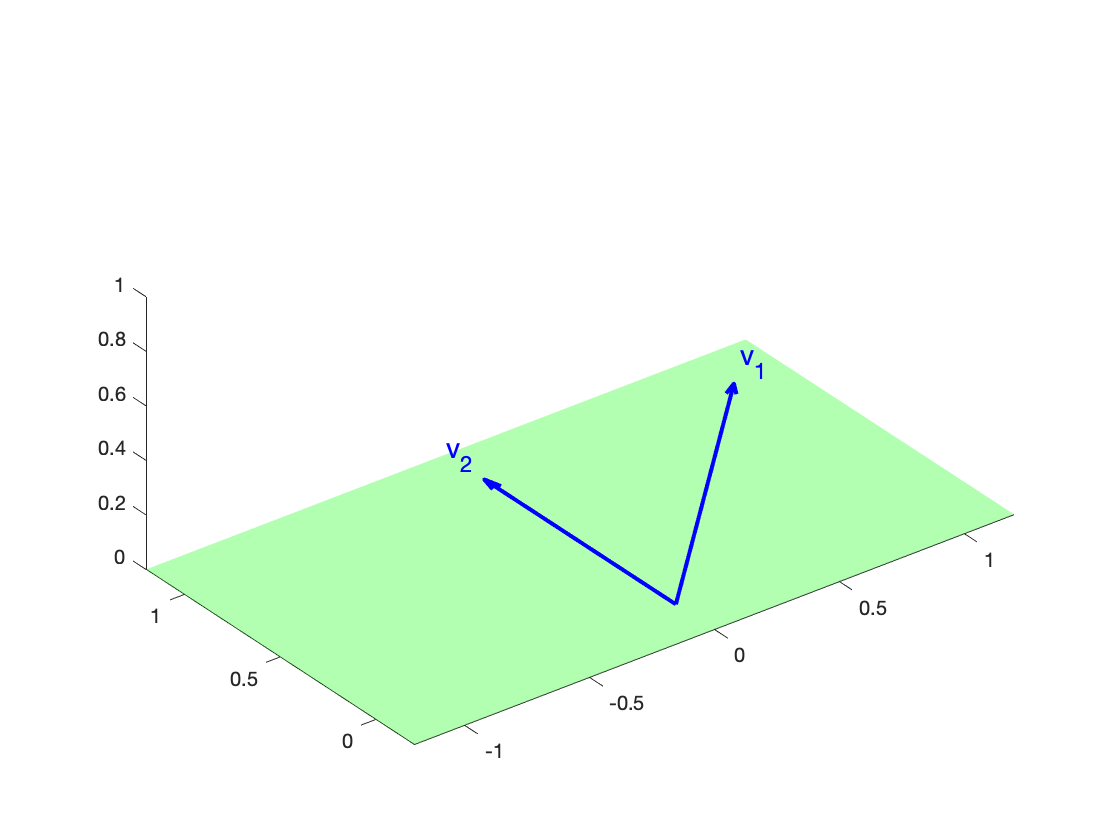

figure
hold on
v1=[1;1;0]; v2=[0;1;0];
s=linspace(-3,3,20);
t=linspace(-3,3,20);
[S,T]=meshgrid(s,t);
X=S;
Y=S+T;
Z=zeros(size(T));
surf(X,Y,Z,'EdgeColor','none','FaceColor','g','FaceAlpha',0.3)
quiver3(0,0,0,v1(1),v1(2),v1(3),0,'LineWidth',2,'Color','b')
quiver3(0,0,0,v2(1),v2(2),v2(3),0,'LineWidth',2,'Color','b')
axis equal
axis([-1.2,1.2,-0.2,1.2,0,1])
text(1.1,1.1,0,'v_1','Color','b','FontSize',14)
text(0,1.2,0,'v_2','Color','b','FontSize',14)
view(3)
hold off

Let's also calculate $\text{proj}_{\textbf w_1}\textbf v_2$ and store it in the variable pw1v2. 

pw1v2=dot(v2,w1)/dot(w1,w1)*w1

pw1v2 =     0.5000
    0.5000
         0


Now we will add the vectors $\textbf w_1$, $\textbf w_2$, $\text{proj}_{\textbf w_1}\textbf v2$ to our image. 

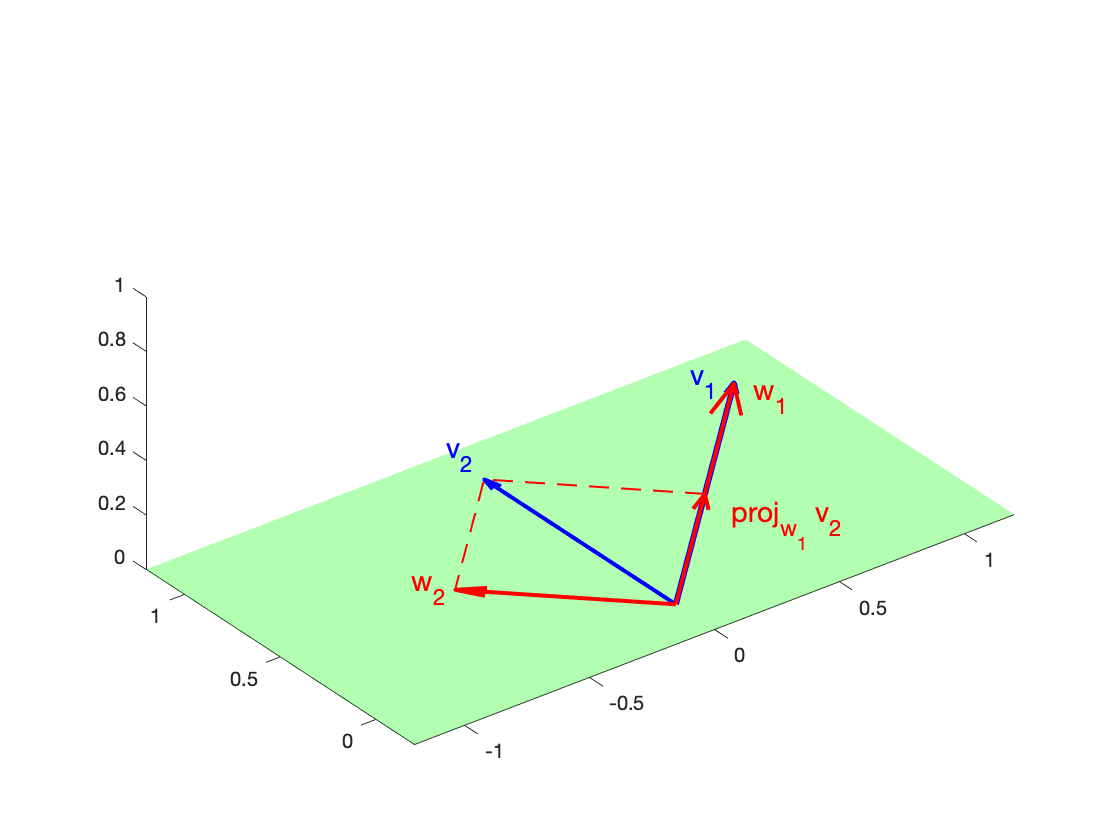

figure
hold on
s=linspace(-3,3,20);
t=linspace(-3,3,20);
[S,T]=meshgrid(s,t);
X=S;
Y=S+T;
Z=zeros(size(T));
surf(X,Y,Z,'EdgeColor','none','FaceColor','g','FaceAlpha',0.3)
quiver3(0,0,0,v1(1),v1(2),v1(3),0,'LineWidth',3,'Color','b')
quiver3(0,0,0,v2(1),v2(2),v2(3),0,'LineWidth',2,'Color','b')
quiver3(0,0,0,w1(1),w1(2),w1(3),0,'LineWidth',2,'Color','r','MaxHeadSize',0.6)
quiver3(0,0,0,w2(1),w2(2),w2(3),0,'LineWidth',2,'Color','r','MaxHeadSize',0.6)
quiver3(0,0,0,p1(1),p1(2),p1(3),0,'LineWidth',2,'Color','r','MaxHeadSize',0.6)
line([pw1v2(1),v2(1),w2(1)],[pw1v2(2),v2(2),w2(2)],[pw1v2(3),v2(3),w2(3)],'LineWidth',1,'LineStyle','--','Color','r')
axis equal
axis([-1.2,1.2,-0.2,1.2,0,1])
text(0.9,1.1,0,'v_1','Color','b','FontSize',14)
text(0,1.2,0,'v_2','Color','b','FontSize',14)
text(-0.6,0.6,0,'w_2','Color','r','FontSize',14)
text(1,0.9,0,'w_1','Color','r','FontSize',14)
text(0.45,0.3,0,'proj_{w_1} v_2','Color','r','FontSize',14)
view(3)
hold off

Thus, we have two orthogonal vectors $\textbf w_1=(1,1,0)^T$ and $\textbf w_2=(-1/2,1/2,0)^T$ in our image. To eliminate the fractions in $\textbf w_2$, we will double each value in $\textbf w_2$ and set $\textbf w_2=(-1,1,0)^T$.

w2=2*w2

$$w2 = \left(\begin{array}{c} -1\\ 1\\ 0 \end{array}\right)$$

Now, we will add our new $\textbf w_1$ and $\textbf w_2$ to a new image and add the remaining vector $\textbf v_3=(0,1,1)^T$.

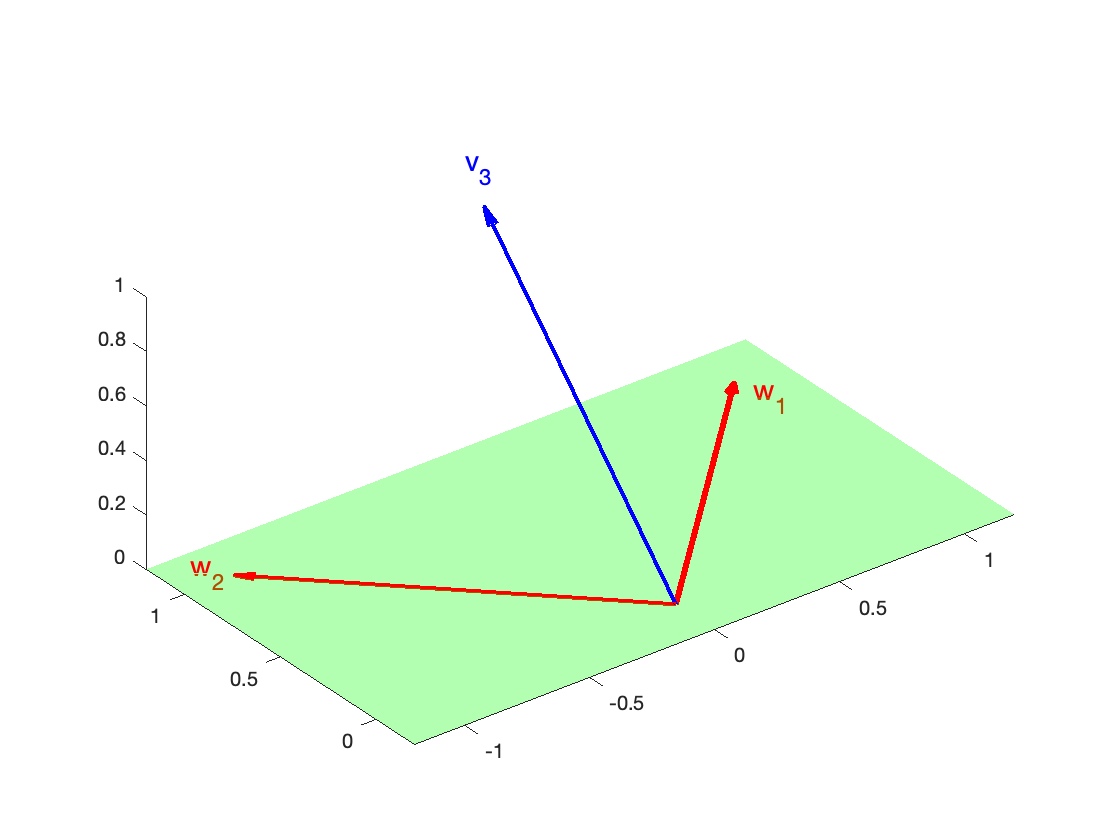

figure
hold on
s=linspace(-3,3,20);
t=linspace(-3,3,20);
[S,T]=meshgrid(s,t);
X=S;
Y=S+T;
Z=zeros(size(T));
surf(X,Y,Z,'EdgeColor','none','FaceColor','g','FaceAlpha',0.3)
quiver3(0,0,0,w1(1),w1(2),w1(3),0,'LineWidth',3,'Color','r')
quiver3(0,0,0,w2(1),w2(2),w2(3),0,'LineWidth',2,'Color','r')
quiver3(0,0,0,v3(1),v3(2),v3(3),0,'LineWidth',2,'Color','b')
axis equal
axis([-1.2,1.2,-0.2,1.2,0,1])
text(1,0.9,0,'w_1','Color','r','FontSize',14)
text(-1.1,1.1,0,'w_2','Color','r','FontSize',14)
text(0,1.1,1.1,'v_3','Color','b','FontSize',14)
view(3)
hold off

Now we will find the projections $\text{proj}_{\textbf w_1}\textbf v_3$ and $\text{proj}_{\textbf w_2}\textbf v_3$, then let $\textbf w=\text{proj}_{\textbf w_1}\textbf v_3+\text{proj}_{\textbf w_1}\textbf v_3$.

pw1v3=dot(v3,w1)/dot(w1,w1)*w1

pw1v3 =     0.5000
    0.5000
         0


pw2v3=dot(v3,w2)/dot(w2,w2)*w2

$$pw2v3 = \left(\begin{array}{c} -\frac{1}{2}\\ \frac{1}{2}\\ 0 \end{array}\right)$$

w=pw1v3+pw2v3

$$w = \left(\begin{array}{c} 0\\ 1\\ 0 \end{array}\right)$$

Now, to understand what is going on, we'll add these to our image.

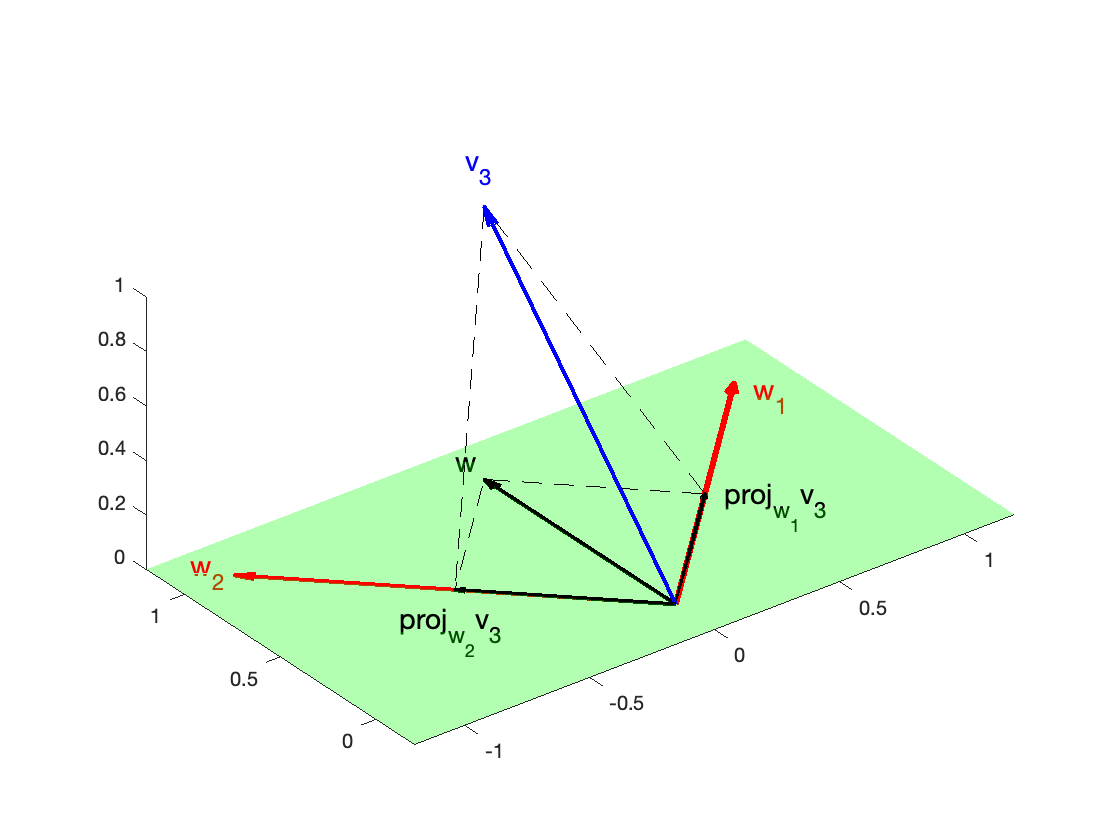

figure
hold on
s=linspace(-3,3,20);
t=linspace(-3,3,20);
[S,T]=meshgrid(s,t);
X=S;
Y=S+T;
Z=zeros(size(T));
surf(X,Y,Z,'EdgeColor','none','FaceColor','g','FaceAlpha',0.3)
quiver3(0,0,0,w1(1),w1(2),w1(3),0,'LineWidth',3,'Color','r')
quiver3(0,0,0,w2(1),w2(2),w2(3),0,'LineWidth',2,'Color','r')
quiver3(0,0,0,v3(1),v3(2),v3(3),0,'LineWidth',2,'Color','b')
quiver3(0,0,0,pw1v3(1),pw1v3(2),pw1v3(3),0,'LineWidth',2,'Color','k')
quiver3(0,0,0,pw2v3(1),pw2v3(2),pw2v3(3),0,'LineWidth',2,'Color','k')
quiver3(0,0,0,w(1),w(2),w(3),0,'LineWidth',2,'Color','k')
axis equal
axis([-1.2,1.2,-0.2,1.2,0,1])
text(1,0.9,0,'w_1','Color','r','FontSize',14)
text(-1.1,1.1,0,'w_2','Color','r','FontSize',14)
text(0,1.1,1.1,'v_3','Color','b','FontSize',14)
text(0.5,0.4,0,'proj_{w_1}v_3','Color','k','FontSize',14)
text(-0.8,0.4,0,'proj_{w_2}v_3','Color','k','FontSize',14)
text(0,1.15,0,'w','Color','k','FontSize',14)
line([pw1v3(1),v3(1),projw2v3(1)],[pw1v3(2),v3(2),projw2v3(2)],[pw1v3(3),v3(3),projw2v3(3)],...
    'LineStyle','--','Color','k')
line([pw1v3(1),w(1),projw2v3(1)],[pw1v3(2),w(2),projw2v3(2)],[pw1v3(3),w(3),projw2v3(3)],...
    'LineStyle','--','Color','k')
view(3)
hold off

Now we will calculate the vector $\textbf v_3-\textbf w$ to our image, which we will save in the variable w3.

w3=v3-w

$$w3 = \left(\begin{array}{c} 0\\ 0\\ 1 \end{array}\right)$$

Now we will add the vector $\textbf w_3=\textbf v_3-\textbf w$ to our image. Note that the command

quiver3(w(1),w(2),w(3),w3(1),w3(2),w3(3),0,'LineWidth',2,'Color','r')

starts the vector $\textbf w_3$ at the tip of the vector $\textbf w$.

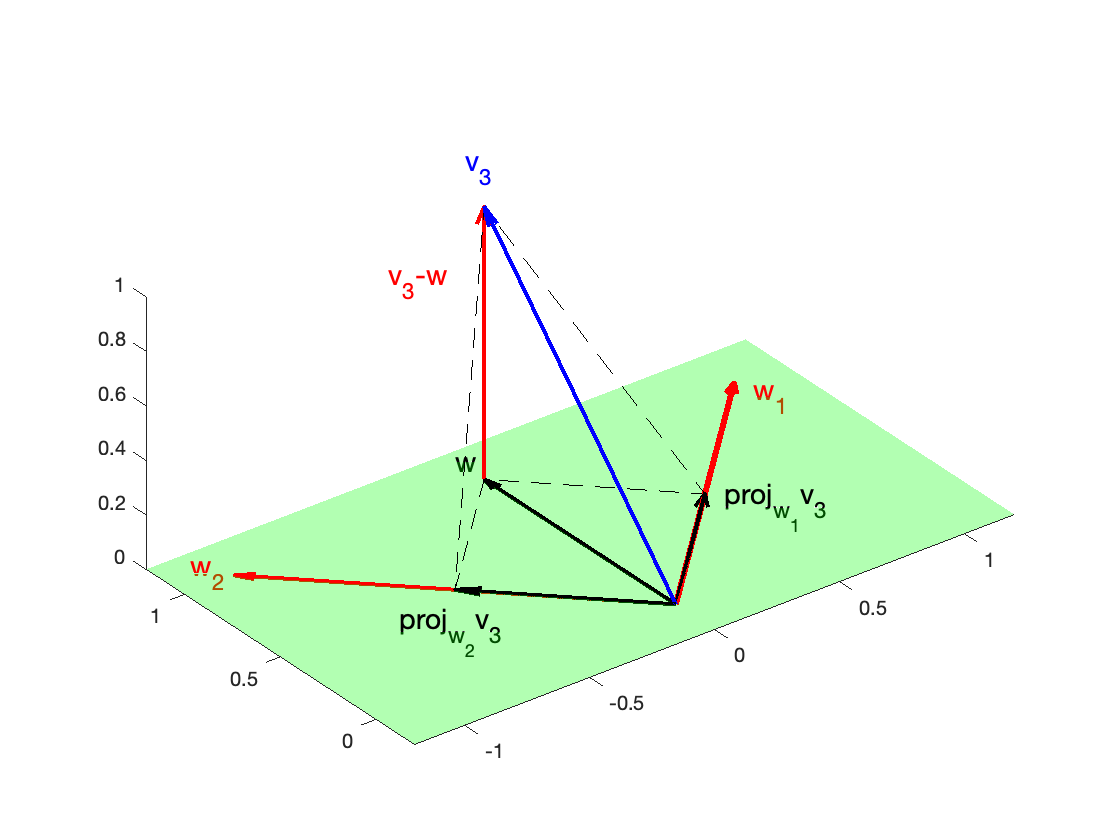

figure
hold on
s=linspace(-3,3,20);
t=linspace(-3,3,20);
[S,T]=meshgrid(s,t);
X=S;
Y=S+T;
Z=zeros(size(T));
surf(X,Y,Z,'EdgeColor','none','FaceColor','g','FaceAlpha',0.3)
quiver3(0,0,0,w1(1),w1(2),w1(3),0,'LineWidth',3,'Color','r')
quiver3(0,0,0,w2(1),w2(2),w2(3),0,'LineWidth',2,'Color','r')
quiver3(0,0,0,v3(1),v3(2),v3(3),0,'LineWidth',2,'Color','b')
quiver3(0,0,0,pw1v3(1),pw1v3(2),pw1v3(3),0,'LineWidth',2,'Color','k','MaxHeadSize',.5)
quiver3(0,0,0,pw2v3(1),pw2v3(2),pw2v3(3),0,'LineWidth',2,'Color','k','MaxHeadSize',.5)
quiver3(0,0,0,w(1),w(2),w(3),0,'LineWidth',2,'Color','k')
quiver3(w(1),w(2),w(3),w3(1),w3(2),w3(3),0,'LineWidth',2,'Color','r')
line([pw1v3(1),v3(1),projw2v3(1)],[pw1v3(2),v3(2),projw2v3(2)],[pw1v3(3),v3(3),projw2v3(3)],...
    'LineStyle','--','Color','k')
line([pw1v3(1),w(1),projw2v3(1)],[pw1v3(2),w(2),projw2v3(2)],[pw1v3(3),w(3),projw2v3(3)],...
    'LineStyle','--','Color','k')
axis equal
axis([-1.2,1.2,-0.2,1.2,0,1])
text(1,0.9,0,'w_1','Color','r','FontSize',14)
text(-1.1,1.1,0,'w_2','Color','r','FontSize',14)
text(0,1.1,1.1,'v_3','Color','b','FontSize',14)
text(0.5,0.4,0,'proj_{w_1}v_3','Color','k','FontSize',14)
text(-0.8,0.4,0,'proj_{w_2}v_3','Color','k','FontSize',14)
text(0,1.15,0,'w','Color','k','FontSize',14)
text(0,1.5,0.5,'v_3-w','Color','r','FontSize',14)
view(3)
hold off

This image should give good visual evidence that the vector $\textbf w_3=\textbf y_3-\textbf w$ is orthogonal to the plane spanned by the orthogonal vectors $\textbf w_1$ and $\textbf w_2$. Thus, to find a third vector $\textbf w_3$ that is orthogonal to the space spanned by our current vectors $\textbf w_1$ and $\textbf w_2$, we will make an orthogonal projection of $\textbf v_3$ onto the space spanned by $\textbf w_1$ and $\textbf w_2$, then subtract the result from $\textbf v_3$.


$$\begin{array}{rcl}
\textbf w_3&=&\textbf v_3-(\text{proj}_{\textbf w_1}\textbf v_3+\text{proj}_{\textbf w_2}\textbf v_3)\\
\textbf w_3&=&\textbf v_3-\frac{\textbf v_3\cdot\textbf w_1}{\textbf w_1\cdot\textbf w_1}\,\textbf w_1-\frac{\textbf v_3\cdot\textbf w_2}{\textbf w_2\cdot\textbf w_2}\,\textbf w_2\\
\textbf w_3&=&\pmatrix{0\cr 1\cr 1}-\frac{(0,1,1)\cdot(1,1,0)}{(1,1,0)\cdot(1,1,0)}\,\pmatrix{1\cr 1\cr 0}-\frac{(0,1,1)\cdot(-1,1,0)}{(-1,1,0)\cdot(-1,1,0)}\,\pmatrix{-1\cr1\cr0}\\
\textbf w_3&=&\pmatrix{0\cr 1\cr 1}-\frac12\pmatrix{1\cr1\cr0}-\frac12\pmatrix{-1\cr1\cr0}\\
\textbf w_3&=&\pmatrix{0\cr 0\cr 1}
\end{array}$$


We can check this calculation with Matlab.

w3=v3-dot(v3,w1)/dot(w1,w1)*w1-dot(v3,w2)/dot(w2,w2)*w2

$$w3 = \left(\begin{array}{c} 0\\ 0\\ 1 \end{array}\right)$$

We can also start the vector $\textbf w_3$ at the origin.

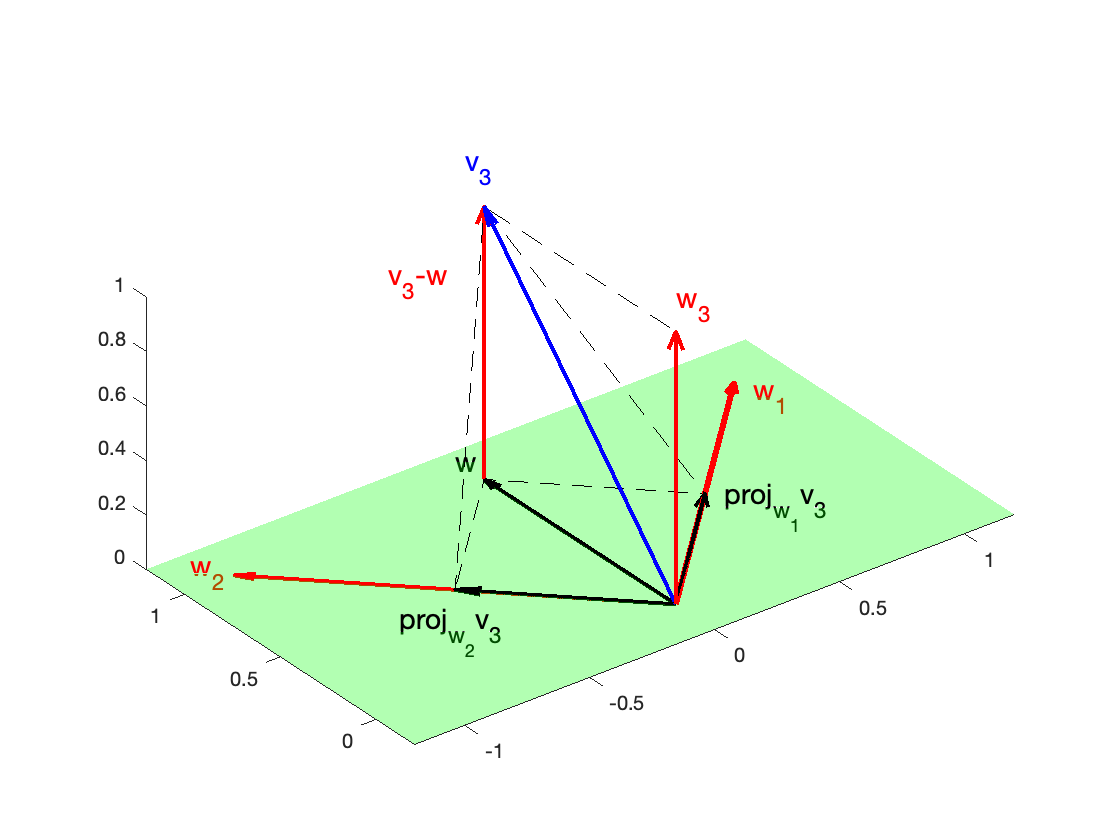

figure
hold on
s=linspace(-3,3,20);
t=linspace(-3,3,20);
[S,T]=meshgrid(s,t);
X=S;
Y=S+T;
Z=zeros(size(T));
surf(X,Y,Z,'EdgeColor','none','FaceColor','g','FaceAlpha',0.3)
quiver3(0,0,0,w1(1),w1(2),w1(3),0,'LineWidth',3,'Color','r')
quiver3(0,0,0,w2(1),w2(2),w2(3),0,'LineWidth',2,'Color','r')
quiver3(0,0,0,v3(1),v3(2),v3(3),0,'LineWidth',2,'Color','b')
quiver3(0,0,0,pw1v3(1),pw1v3(2),pw1v3(3),0,'LineWidth',2,'Color','k','MaxHeadSize',.5)
quiver3(0,0,0,pw2v3(1),pw2v3(2),pw2v3(3),0,'LineWidth',2,'Color','k','MaxHeadSize',.5)
quiver3(0,0,0,w(1),w(2),w(3),0,'LineWidth',2,'Color','k')
quiver3(w(1),w(2),w(3),w3(1),w3(2),w3(3),0,'LineWidth',2,'Color','r')
quiver3(0,0,0,w3(1),w3(2),w3(3),0,'LineWidth',2,'Color','r')
line([pw1v3(1),v3(1),projw2v3(1)],[pw1v3(2),v3(2),projw2v3(2)],[pw1v3(3),v3(3),projw2v3(3)],...
    'LineStyle','--','Color','k')
line([pw1v3(1),w(1),projw2v3(1)],[pw1v3(2),w(2),projw2v3(2)],[pw1v3(3),w(3),projw2v3(3)],...
    'LineStyle','--','Color','k')
line([w3(1),v3(1)],[w3(2),v3(2)],[w3(3),v3(3)],'LineStyle','--','Color','k')
axis equal
axis([-1.2,1.2,-0.2,1.2,0,1])
text(1,0.9,0,'w_1','Color','r','FontSize',14)
text(-1.1,1.1,0,'w_2','Color','r','FontSize',14)
text(0,1.1,1.1,'v_3','Color','b','FontSize',14)
text(0.5,0.4,0,'proj_{w_1}v_3','Color','k','FontSize',14)
text(-0.8,0.4,0,'proj_{w_2}v_3','Color','k','FontSize',14)
text(0,1.15,0,'w','Color','k','FontSize',14)
text(0,1.5,0.5,'v_3-w','Color','r','FontSize',14)
text(0,0,1.1,'w_3','Color','r','FontSize',14)
view(3)
hold off

This image shows how the vector $\textbf v_3$ was projected onto $\textbf w_1$ and $\textbf w_2$ (marked with $\text{proj}_{\textbf w_1}\,\textbf v_3$ and $\text{proj}_{\textbf w_2}\,\textbf v_3$), then their sum was subtracted from $\textbf v_3$ to produce the vector $\textbf w_3$.

# Summary of Our Process for Example #2

We started with a basis $\{\textbf v_1,\ \textbf v_2,\ \textbf v_3\}$, then performed the following steps.


$$\begin{array}{rcl}
\textbf w_1&=&\textbf v_1\\
\textbf w_2&=&\textbf v_2-\frac{\textbf v_2\cdot\textbf w_1}{\textbf w_1\cdot\textbf w_1}\,\textbf w_1\\
\textbf w_3&=&\textbf v_3-\frac{\textbf v_3\cdot\textbf w_1}{\textbf w_1\cdot\textbf w_1}\,\textbf w_1-\frac{\textbf v_3\cdot\textbf w_2}{\textbf w_2\cdot\textbf w_2}\,\textbf w_2\\
\end{array}$$


Some might prefer to write this as:


$$\begin{array}{rcl}
\textbf w_1&=&\textbf v_1\\
\textbf w_2&=&\textbf v_2-\text{proj}_{\textbf w_1}\,\textbf  v_2\\
\textbf w_3&=&\textbf v_3-\text{proj}_{\textbf w_1}\,\textbf  v_3-\text{proj}_{\textbf w_2}\,\textbf  v_3
\end{array}$$


# The Gram-Schmidt Theorem

Hopefully, Examples #1 and #2 have helped us predict a pattern.

Given a basis $B=\{\textbf v_1,\ \textbf v_2,\ \ldots,\ \textbf v_n\}$ be any basis for the inner product space $V$, define:


$$\begin{array}{rcl}
\textbf w_1&=&\textbf v_1\\
\textbf w_2&=&\textbf v_2-\frac{\textbf v_2\cdot\textbf w_1}{\textbf w_1\cdot\textbf w_1}\,\textbf w_1\\
\textbf w_3&=&\textbf v_3-\frac{\textbf v_3\cdot\textbf w_1}{\textbf w_1\cdot\textbf w_1}\,\textbf w_1-\frac{\textbf v_3\cdot\textbf w_2}{\textbf w_2\cdot\textbf w_2}\,\textbf w_2\\
\vdots&=&\vdots\\
\textbf w_n&=&\textbf v_n-\frac{\textbf v_n\cdot\textbf w_1}{\textbf w_1\cdot\textbf w_1}\,\textbf w_1-\frac{\textbf v_n\cdot\textbf w_2}{\textbf w_2\cdot\textbf w_2}\,\textbf w_2-\cdots-\frac{\textbf v_{n}\cdot\textbf w_{n-1}}{\textbf w_{n-1}\cdot\textbf w_{n-1}}\,\textbf w_{n-1}\\
\end{array}$$


# Orthonormal Basis

Now, let's create an orthonormal basis for Example #2. Our orthogonal basis vectors are:


$$\textbf w_1=\pmatrix{1\cr 1\cr 0},\qquad\textbf w_2=\pmatrix{-1\cr 1\cr 0},\qquad\text{and}\qquad\textbf w_3=\pmatrix{0\cr 0\cr 1}$$


Note that $||\textbf w_1||=\sqrt2$, $||\textbf w_2||=\sqrt2$, and $||\textbf w_3||=1$, so when we divide each of these vectors by their lengths, we get the following orthonormal basis.


$$\textbf u_1=\pmatrix{1/\sqrt2\cr 1/\sqrt2\cr 0},\qquad\textbf u_2=\pmatrix{-1/\sqrt2\cr 1/\sqrt 2\cr 0},\qquad\text{and}\qquad\textbf u_1=\pmatrix{0\cr 0\cr 1}$$


or equivalently,


$$\textbf u_1=\pmatrix{\sqrt2/2\cr \sqrt2/2\cr 0},\qquad\textbf u_2=\pmatrix{-\sqrt2/2\cr \sqrt 2/2\cr 0},\qquad\text{and}\qquad\textbf u_1=\pmatrix{0\cr 0\cr 1}$$


**Fast Way to Check: ** Again, a fast way to check is to place the original vectors 


$$\textbf v_1=\pmatrix{1\cr 1\cr 0},\qquad\textbf v_2=\pmatrix{0\cr 1\cr 0},\qquad\text{and}\qquad\textbf v_3=\pmatrix{0\cr 1\cr 1}$$
 

into a matrix A and use Matlab's orth command.

A=[v1,v2,v3];
orth(sym(A))

$$ans = \left(\begin{array}{ccc} \frac{\sqrt{2}}{2} & -\frac{\sqrt{2}}{2} & 0\\ \frac{\sqrt{2}}{2} & \frac{\sqrt{2}}{2} & 0\\ 0 & 0 & 1 \end{array}\right)$$

Wow! So quick. The columns of this answer contains the same orthonormal vectors found by our hand-calculations. :-)